# Visual degrees and retinal mm

It is sometimes necessary to convert measurements made along the retina from one set of units (degrees of visual angle) to another (millimeters). While there are rules-of-thumb for this conversion (e.g., 0.3 mm / degree), the precise value is complicated to obtain. This is because of individual varation in the ellipsoidal dimensions of the retina, as well as in the optics and accommodative state of the eye.

This demo explores the concepts and details related to this conversion.

## A basic calculation of mm retina / degrees visual angle

Keeping things simple, we can define a default model eye, and measure the unit conversion for the vertex point on the longitudinal axis of the retina:

eye = modelEyeParameters();
calcMmRetinaPerDeg(eye)

ans = 0.2815

## Visual degrees at the fovea

To be a bit more precise, we can define visual angle with respect to the approximate incident nodal point of the eye, and the field location as corresponding to the fovea:

fieldAngularPosition = eye.landmarks.fovea.degField;
rayOriginDistance = 1500;
angleReferenceCoord = eye.landmarks.incidentNode.coords;

We now call the function with these optional inputs:

mmPerDeg = calcMmRetinaPerDeg(eye,fieldAngularPosition,rayOriginDistance,angleReferenceCoord)

mmPerDeg = 0.2810

As can be seen, there is a small difference in the unit relationship depending upon the position in the visual field that we choose to interogate.

## Unit conversion as a function of field position

We can repeat the calculation, now for positions along the horizontal meridian, relative to the fovea, and plot the resulting function:

horizontalOffset = -40:5:40;
for ii = 1:length(horizontalOffset)
    thisLocation = [horizontalOffset(ii)+fieldAngularPosition(1), fieldAngularPosition(2)];
    mmPerDeg(ii) = calcMmRetinaPerDeg(eye,thisLocation,rayOriginDistance,angleReferenceCoord);
end
figure
plot(horizontalOffset,mmPerDeg,'-k')
ylabel('mm/deg');
xlabel('horizontal field location relative to fovea [deg]');
xlim([-40 40])

## Comparison to Drasdo & Fowler

One of the "species" of model eye available in the software is Drasdo & Fowler 1974. We can examine the behavior of this model eye.

eyeDrasdo = modelEyeParameters('species','Drasdo');
fieldAngularPosition = eyeDrasdo.landmarks.fovea.degField;
angleReferenceCoord = eyeDrasdo.landmarks.incidentNode.coords;

for ii = 1:length(horizontalOffset)
    thisLocation = [horizontalOffset(ii)+fieldAngularPosition(1), fieldAngularPosition(2)];
    mmPerDeg(ii) = calcMmRetinaPerDeg(eyeDrasdo,thisLocation,rayOriginDistance,angleReferenceCoord);
end
hold on
plot(horizontalOffset,mmPerDeg,'-r')

The result is similar to that provided by the current model eye, although with lower values overall. This may be attributed to small differences in the axial length of the modeled eyes, and the location of the approximate nodal points.

## Visual field position

Given an eye in a particular accommodative state, and given a point in object space, there is a unique location on the retina where that point is imaged (even if that point is the central tendency of a blurred area). What becomes complicated, however, is when we wish to describe the location in object space in terms of *angular visual field* position. With some consideration we come to realize that the assignment of an angular position to a point in object space depends upon specification of points of reference, and that these points of reference can change.

It is often useful to identify points in object space by their visual field position. This is expressed as the horizontal and vertical angles (in, e.g., degrees) of a point in object space with respect to an eye-based coordinate frame. In casual usage, the eye-based coordinate frame may have its origin at the front of the eye, with the horizontal and vertical planes defined with respect to gravity. One advantage of describing locations in terms of visual field position, and size in terms of visual degrees, is that the absolute distance of the object need not be specified.

This simple definition of visual angle is good enough in most circumstances. If, however, greater precision is waranted, then the next stage of complexity is to define visual field position with respect to the* nodal points *of the eye. In a simple, paraxial optical system, a ray directed towards the *incident* node will appear to leave from the optical system at the *emergent* node unchanged in direction of travel (i.e., the incident and emergent rays are parallel). A ray that has the property of entering and exiting an optical system traveling in the same direction is termed a *nodal ray*.

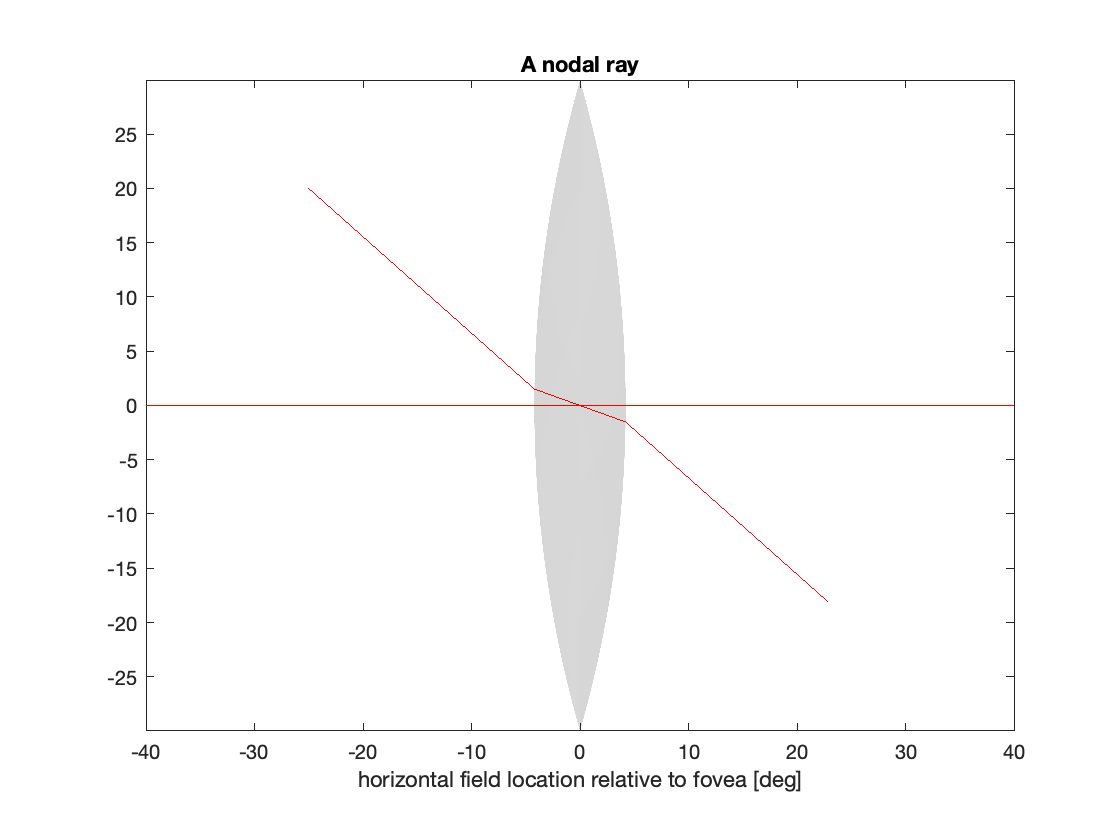

opticalSystem = addBiconvexLens( initializeOpticalSystem, 0, 20, 30, 2);
[rayPath,outputRay] = findNodalRay([-25,0,20],opticalSystem);
figure
plotOpticalSystem(opticalSystem,'newFigure',false,'rayPath',rayPath,'outputRay',outputRay,'outputRayScale',25);
view(0,0);
xlim([-40 40])
title('A nodal ray');

Given the incident and emergent nodes of an eye, one may assert that nodal rays arising from a particular visual field position will enter the optics of the eye and exit towards the retina at the same angles, creating a nice correspondence between points in object space and points on the retina.

However, this characterization of visual angle masks further complexity. The eye (and the model eye) optical system does not have unique nodal points. While one may estimate an approximation to the incident and emergent nodal points, this estimated location itself will change depending upon (e.g.) the accommodative state of the eye. Moreover, there is no guarantee that a nodal ray that arises from a particular visual field location will pass through the approximate incident nodal point, or even arrive on the retina at the central position of a bundle of rays that arise from that same location in object space.

For this reason, it is sometimes useful to distinguish between *reference* field position (which is a tag assigned to locations in object space that will be considered relatively invariant between observers and accommodative states of the eye), and *current* field position (which is the angular position of a point in object space with respect to the current approximate incident node of the eye.

## Specifying points in object space

We can specify a point in object space with the following information:

- fieldAngularPosition

- angleReferenceCoord

- rayOriginDistance

- distanceReferenceCoord

The routines allow specification of a point in object space that has an angular position with reference to one point, and a distance from a different reference point. The need for this derives from the differing reference locations for consideration of visual field angle, and the accommodative state of the eye.

As discussed above, visual field angle is often defined with respect to the (approximate) incident nodal point of the eye. Sometimes it is also important to specify the distance of a point from the eye. The accommodative state of the eye is expressed in reciprocal distance (diopters), with the distance calculated relative to the first principal point of the eye. The function `calcFieldRay` converts this set of values into a location in object space.